# Acceleration

Le script suivant permet de simuler une acceleration sur une distance donnée. De nombreuses ameliorations peuvent etre apportees par la suite. Ce script est utile pour voir l'influence des differents parametres sur le temps de l'acceleration

## Hypotheses

- Le pneu est indeformable

- Le coeff de résistance au roulement est constant

- Le transfert de charge est instantane

- Les pertes dans la transmission sont proportionnelles au couple

- L'appui est neglige

- La trainée est celle d'invictus

## Parametres

% clear all
% close all

g = 9.81; % Pesanteur (m/s²)

% Epreuve et pilotage
D_tot = 75; % Longueur de la piste (m)
m_p = 75; % Masse du pilote (kg)
h_g_p = 0.42; % Hauteur du centre de gravite du pilote (m)

% Transmission
k_p =[0.1:1/200:0.5]; % Rapport primaire
pertes = 0.95; % Coefficient de pertes de couple dans la transmission

% Pneumatiques
% Pas de glissement
coeff_adh = 1.55;
sl =0;
coeff_roul = 0.01; % Coefficient de resistance au roulement du pneu
cx=0.665;

% Base roulante
m_v = 222; % Masse du vehicule (kg)
h_g_v = 0.3; % Hauteur du centre de gravite de la voiture (m)
emp = 1.575; % Empattement (m)
rep = 0.55; % Masse sur l'essieu arrière en statique (%)
D_roue = 0.52; % Diametre exterieur de la roue (m)
Jjp = 0.3046 ; %Inertie de la roue et du pneu (CATIA)
Jm = 0.005; %Inertie du moyeu et du freinage (CATIA)
Ja = 0; %inertie d'un arbre de transmission  (CATIA)
Jc = 0.005; % Inertie de la couronne (CATIA)
Jmot = 0.1; % Estimation de l'inertie moteur+ chaine
m = m_v + m_p; % Masse totale (kg)
h_g = (m_v*h_g_v+m_p*h_g_p)/m; % Hauteur du centre de gravite (m)
b = coeff_roul*2/D_roue; % Decalage du point d'appui (m)
c_roul = m*g*b; % Resistance au roulement (N.m)


%Moteur emrax 90N.m
rmot=[0:200:6400];
cmot=2*90; %N.m


## Simulation


% Paramètres simulation
Trapport=[];
pas = 0.001; % Pas de simulation (s)

for i =1:length(k_p);
    % Initialisation
    d = 0; % distance parcourue
    r = 0; % regime moteur au depart
    v = 0; % vitesse du vehicule
    t = -pas; % temps
    T = [0]; % Temps
    V = [0]; % Vitesse
    a = 0; %acceleration instantannée
    A = [0]; % Acceleration en g
    R = [0]; % Regime
    C = [0]; % Couple
    D = [0]; % Distance
    T_pas = [];
    Adh = [1]; % Risque de patinage des pneus
    Ch_ar = [rep*m*g];
    Kp=k_p(i);
    J_eq = 2*(Jmot+Kp^2*(Ja+Jc+Jjp))+m_v*Kp^2*(D_roue/2)^2; % Inertie equivalente des masses en rotation(kg.m²)
    c_trans = coeff_adh*m*g*rep*D_roue/2; % Couple maximum transmissible   
    while d < D_tot
        t = t+pas; 
        T = [T t];
        tr = 60*v/(3.14*D_roue*Kp); % Calcul du regime moteur
        
        % Acceleration
        if tr<6500 & cmot<c_trans; %condition de non patinage et de respect de la plage de puissance du moteur
            c_k = cmot;
            a_ang = (c_k/Kp-c_roul-cx*v^2)/J_eq; % Acceleration angulaire des roues arrieres
            c_trans = coeff_adh*m*g*D_roue/2*(rep+a*h_g); % Couple maximum transmissible avec transfert de charges 
            C = [C, c_k]; % Memoire du couple aux roues         
            Ch_ar =[Ch_ar c_trans]; % Memoire de la charge sur les roues arrieres

            a = (1-sl)*a_ang*D_roue/2; % Acceleration du vehicule en m/s²
            A = [A,a/10]; % Memoire acceleration en g
        
        elseif tr>=6500;
            tr=6500;
            
            a=0;
        else;
            c_k = c_trans; % Prise en compte de la limite d'adherence des pneus
            a_ang = (c_k/Kp-c_roul-cx*v^2)/J_eq; % Acceleration angulaire des roues arrieres
            c_trans = coeff_adh*m*g*D_roue/2*(rep+a*h_g); % Charge sur l'essieu arrière avec prise en compte du transfert de masse
            a = (1-sl)*a_ang*D_roue/2; % Acceleration du vehicule en m/s²
        end
    
        v = v + a*pas; % Vitesse du vehicule
        V = [V v]; % Memoire de la vitesse
        d = d + v*pas; % Distance parcourue
        D = [D, d]; % Memoire de la distance
        tr = 60*v/(3.14*D_roue*Kp); % Calcul du regime moteur
    end
    Trapport=[Trapport, t];
end

## Principaux resultats

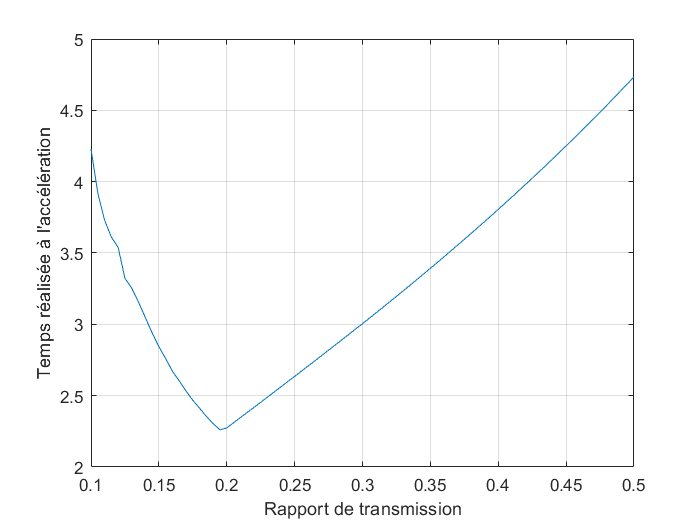

figure('Name','Choix du rapport de transmission')
plot(k_p,Trapport)
grid()
xlabel('Rapport de transmission');
ylabel("Temps réalisée à l'accélération");

disp('Temps (s) :')

Temps (s) :


disp(min(Trapport))

    2.2600



disp('Vitesse max (km/h) :')

Vitesse max (km/h) :


disp(max(V)*3.6)

   69.4502



disp('Acceleration max (g) :')

Acceleration max (g) :


disp(max(A))

    1.5698



if max(Ch_ar) == m*g
    disp('Wheeliiiinnngg ! :p')
end
disp('---------------------------------------------------------')

---------------------------------------------------------
